# FNN CNN LSTM - Generate Models

시간별 입력을 이해하는 것이 중요하다.

Here input `x` and targets `t` define a simple function that you can plot:

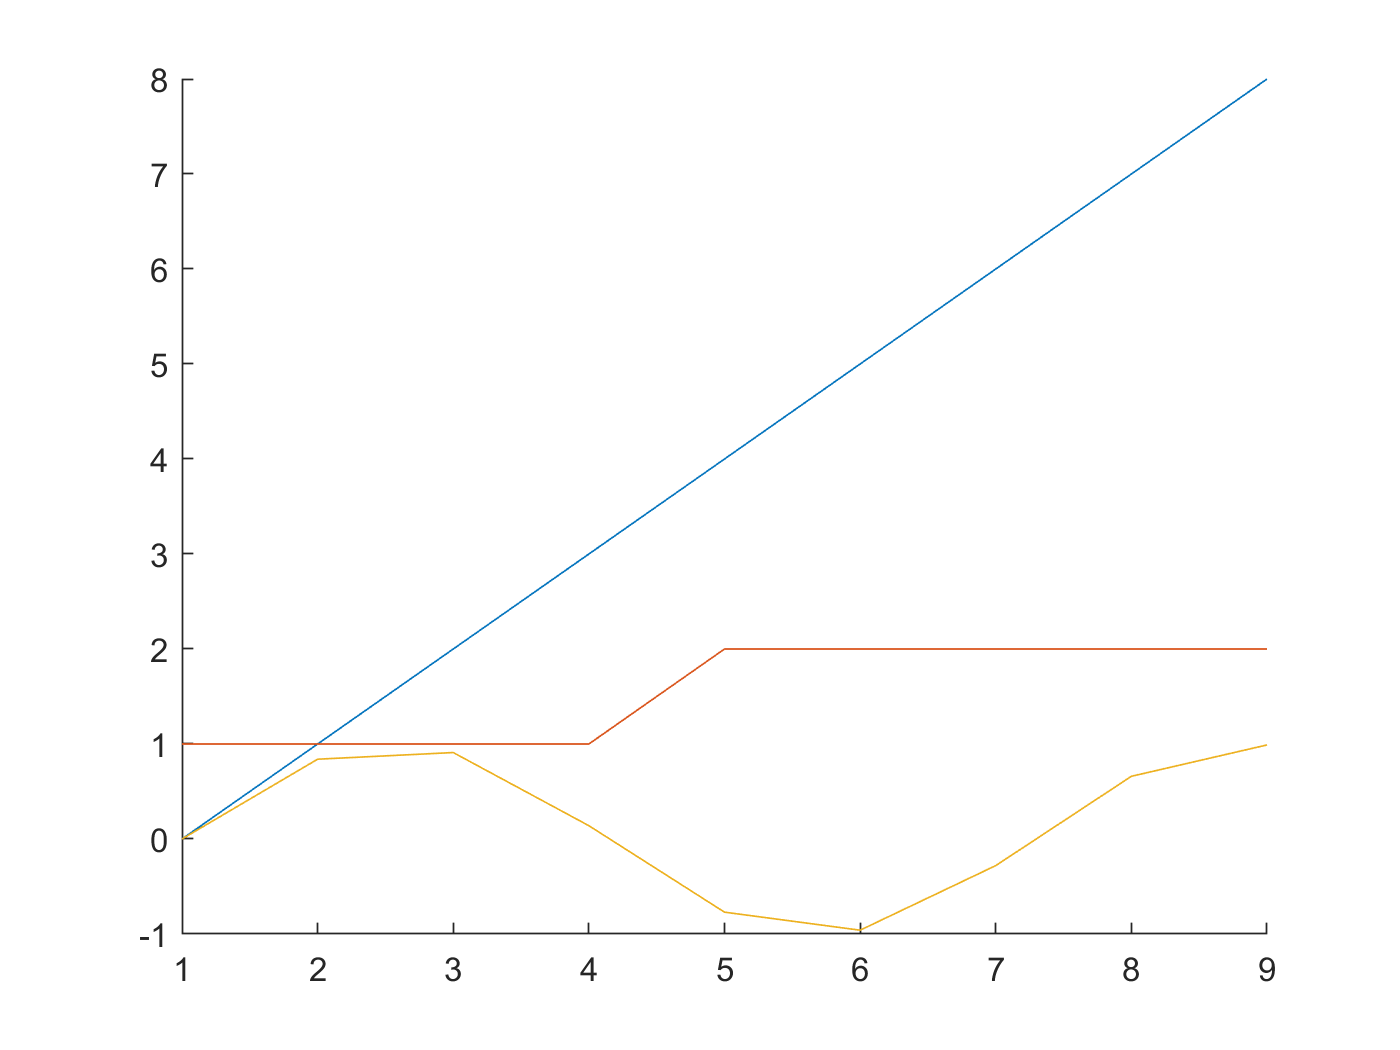

a = [0 1 2 3 4 5 6 7 8];
b = [1 1 1 1 2 2 2 2 2];
x = [a;b];
t = [0 0.84 0.91 0.14 -0.77 -0.96 -0.28 0.66 0.99];
figure; hold on; plot(a); plot(b); plot(t); hold off  

Here `feedforwardnet` creates a two-layer feed-forward network. The network has one hidden layer with ten neurons.

net = feedforwardnet(10);
net = configure(net,x,t);
y1 = net(x)

y1 =     1.9627    1.7726    1.2306    0.4718   -1.0816   -1.2971   -0.7327   -0.4704   -0.4439


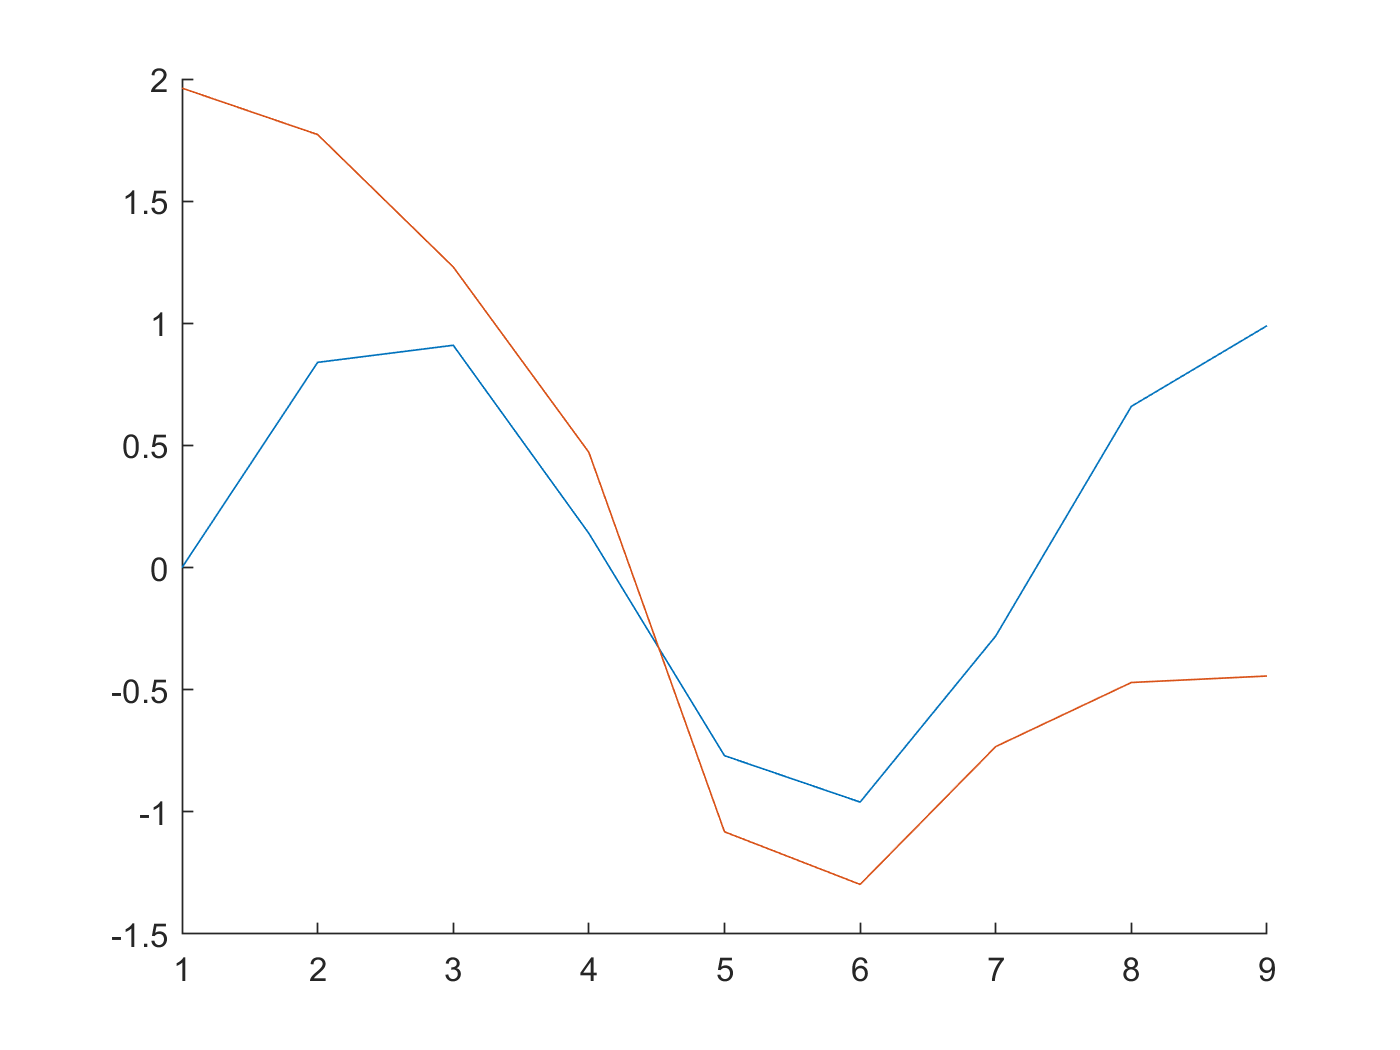

%plot(x,t,'o',x,y1,'x')
figure; hold on; plot(t); plot(y1); hold off  

The network is trained and then resimulated.

net = train(net,x,t);
y2 = net(x)

y2 =     0.5668    0.5863    0.5928   -0.0125   -0.6482   -0.6311    0.0207    0.6591    0.7473


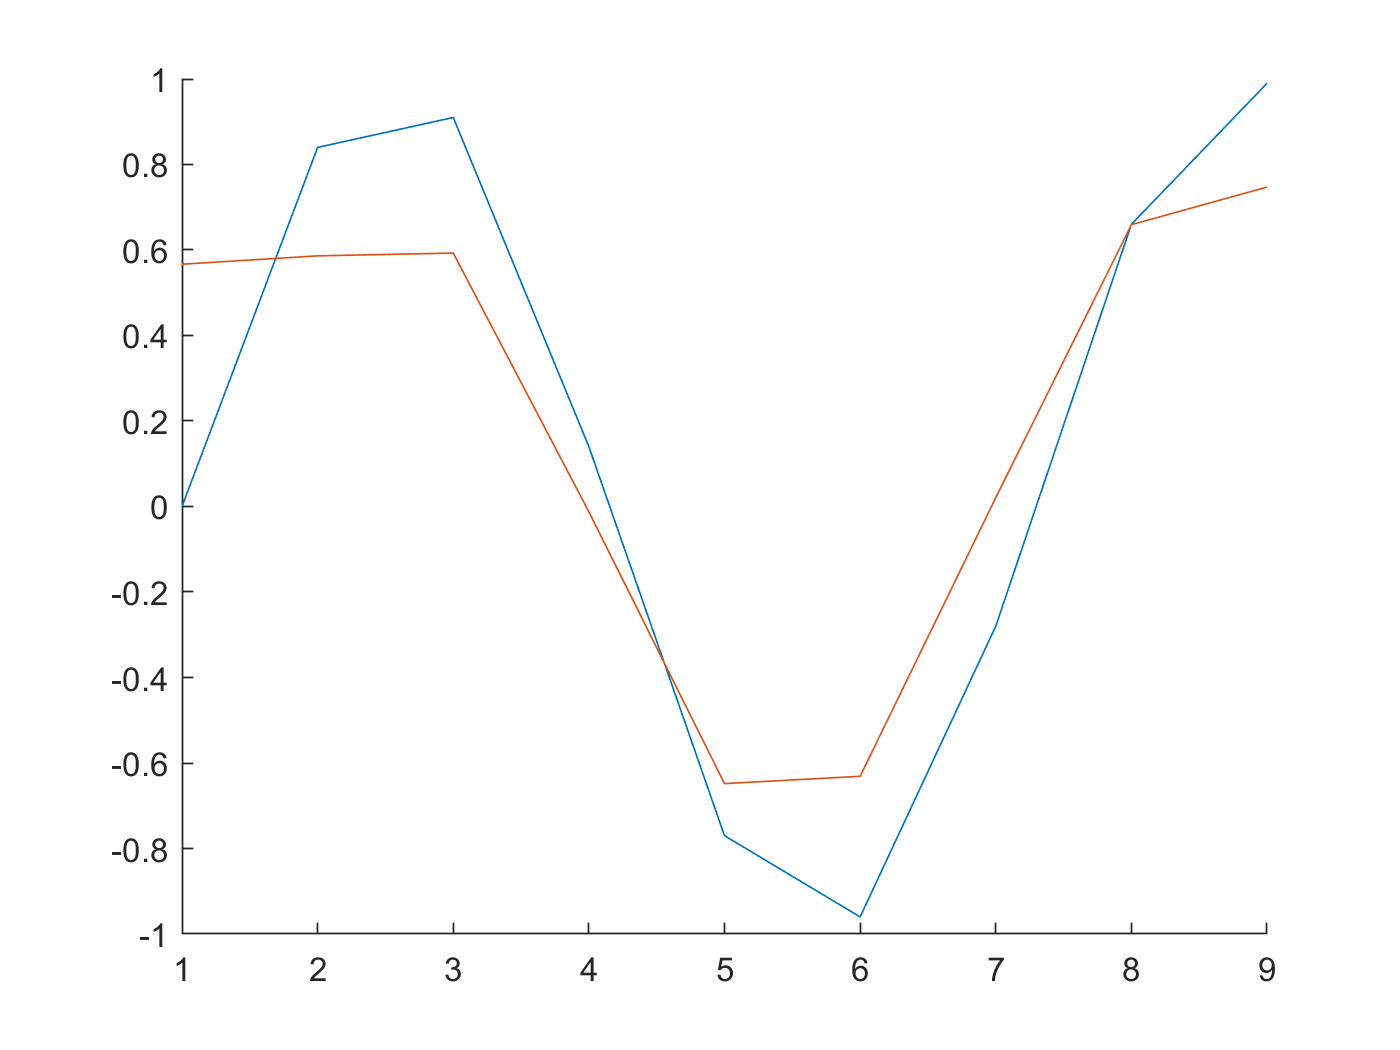

%plot(x,t,'o',x,y1,'x',x,y2,'*')
figure; hold on; plot(t); plot(y2); hold off  

# 저장된 데이타를 모두 읽어들인다.

clear
load ryan_gen_data    

# x = 05plus06plus07 y = pattern  - 출력값 = 유저패턴 = drop voltage 

BatteryNum = 56731;
Train_Input = x_05plus06plus07;
Train_Output = yPattern_05plus06plus07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.22 |         0.25 |       0.0241 |       0.0304 |          0.0010 |
|      13 |          50 |       00:00:07 |         0.14 |         0.15 |       0.0099 |       0.0109 |          0.0010 |
|      25 |         100 |       00:00:08 |         0.14 |         0.14 |       0.0100 |       0.0100 |          0.0010 |
|      38 |         150 |       00:00:09 |         0.13 |         0.14 |       0.0088 |   

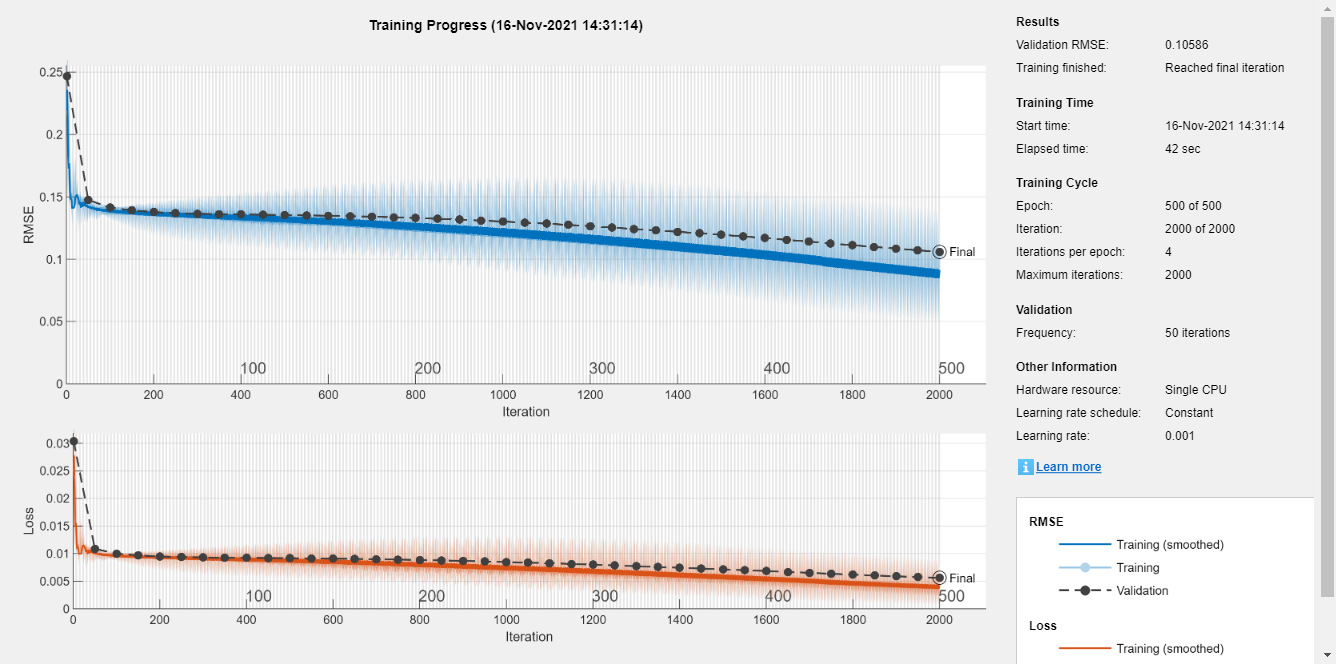

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.21 |         0.20 |       0.0220 |       0.0199 |          0.0010 |
|      13 |          50 |       00:00:04 |         0.15 |         0.14 |       0.0108 |       0.0098 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.13 |         0.14 |       0.0080 |       0.0097 |          0.0010 |
|      38 |         150 |       00:00:06 |         0.14 |         0.14 |       0.0101 |   

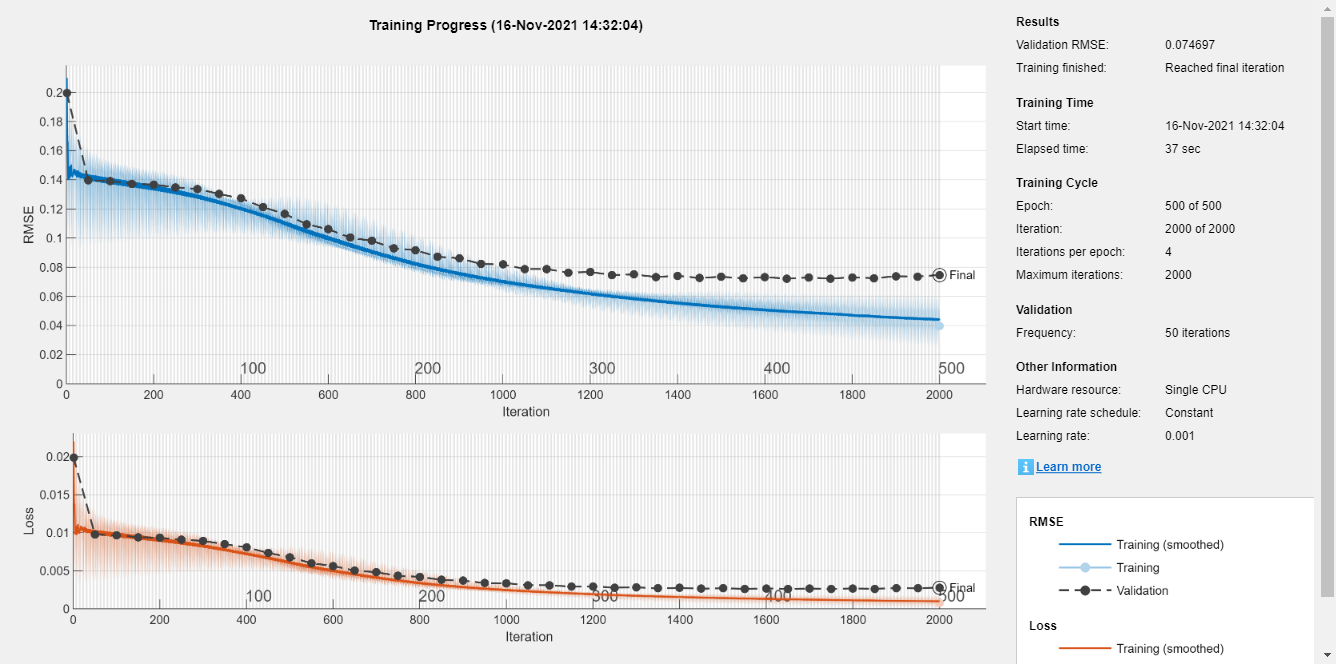

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.23 |         0.20 |       0.0258 |       0.0200 |          0.0010 |
|      13 |          50 |       00:00:05 |         0.15 |         0.14 |       0.0109 |       0.0097 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.14 |         0.14 |       0.0098 |       0.0096 |          0.0010 |
|      38 |         150 |       00:00:07 |         0.14 |         0.14 |       0.0103 |       0.0093 |          0.0010 |
|      5

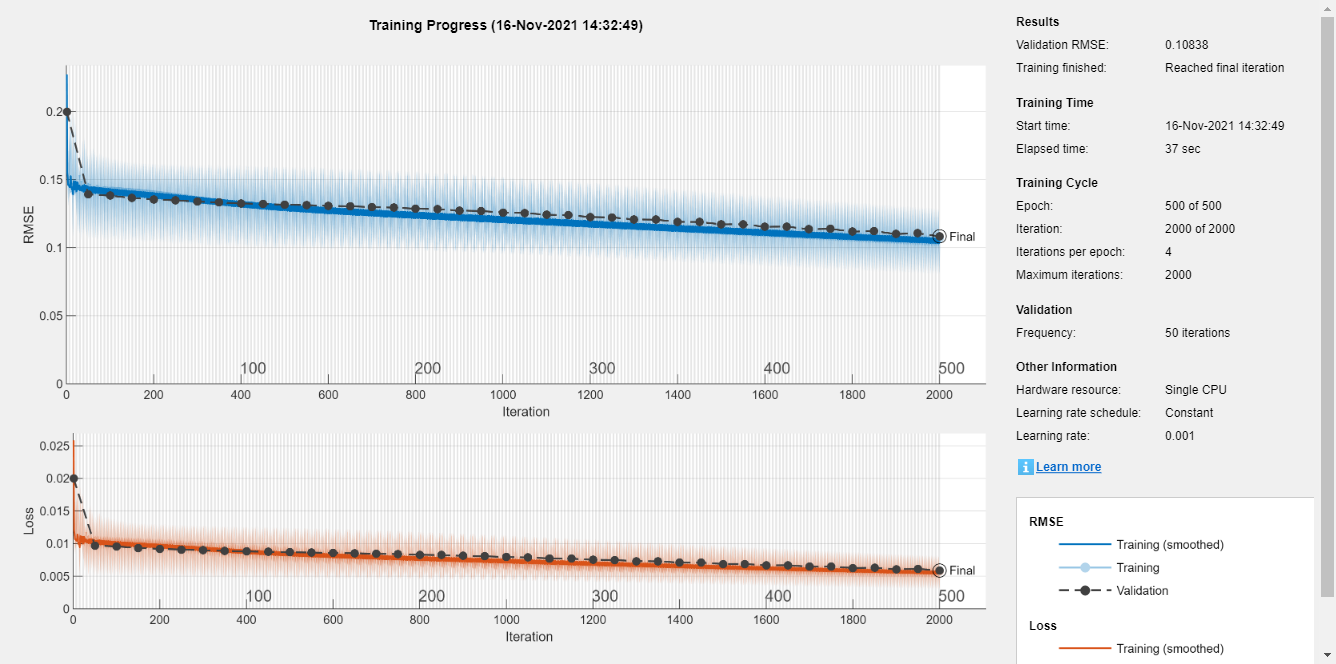

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.24 |         0.21 |       0.0288 |       0.0215 |          0.0010 |
|      13 |          50 |       00:00:05 |         0.14 |         0.14 |       0.0100 |       0.0100 |          0.0010 |
|      25 |         100 |       00:00:06 |         0.14 |         0.14 |       0.0102 |       0.0097 |          0.0010 |
|      38 |         150 |       00:00:07 |         0.13 |         0.14 |       0.0091 |       0.0092 |          0.0010 |
|      5

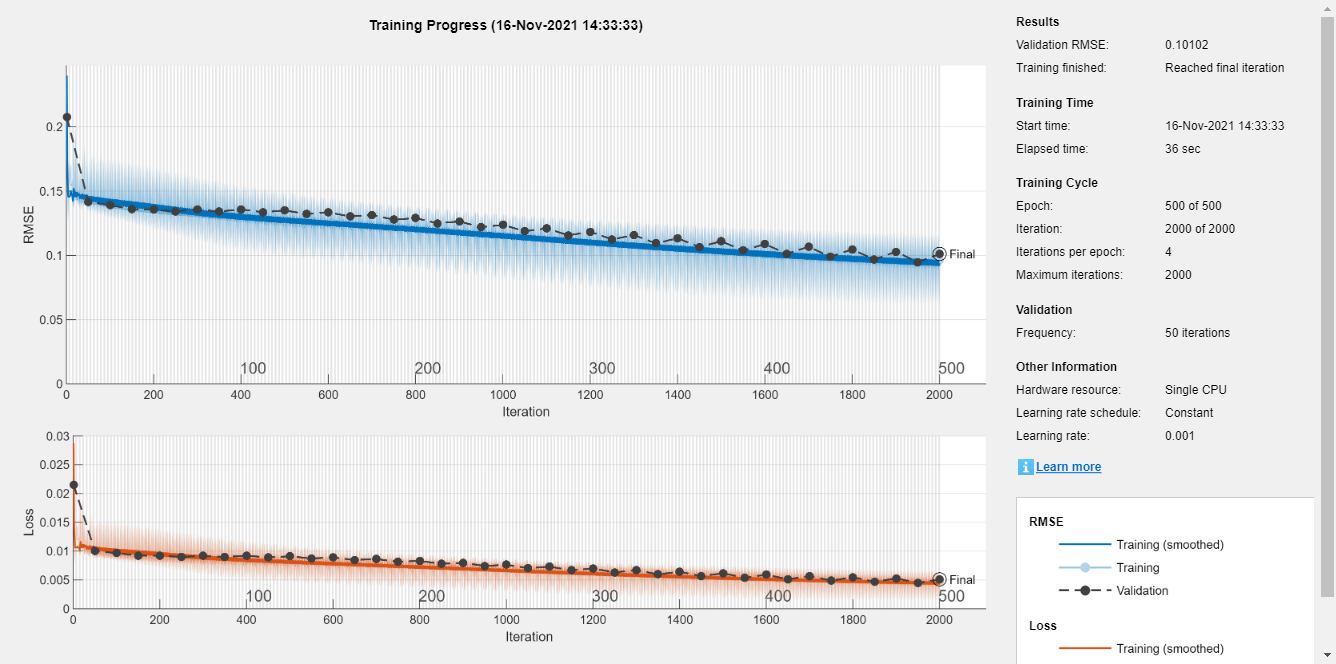

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06plus07_pattern_v2 = netFNN40;
netCNN1_05plus06plus07_pattern_v2 = netCNN1;
netCNN2_05plus06plus07_pattern_v2 = netCNN2;
netLSTM_05plus06plus07_pattern_v2 = netLSTM;
netGRU_05plus06plus07_pattern_v2 = netGRU;



# x = 05plus06plus07 y = cap 

BatteryNum = 5673;
Train_Input = x_05plus06plus07;
Train_Output = yCap_05plus06plus07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.37 |         0.32 |       0.0685 |       0.0504 |          0.0010 |
|      13 |          50 |       00:00:06 |         0.08 |         0.08 |       0.0035 |       0.0035 |          0.0010 |
|      25 |         100 |       00:00:07 |         0.05 |         0.05 |       0.0015 |       0.0012 |          0.0010 |
|      38 |         150 |       00:00:08 |         0.04 |         0.04 |       0.0008 |   

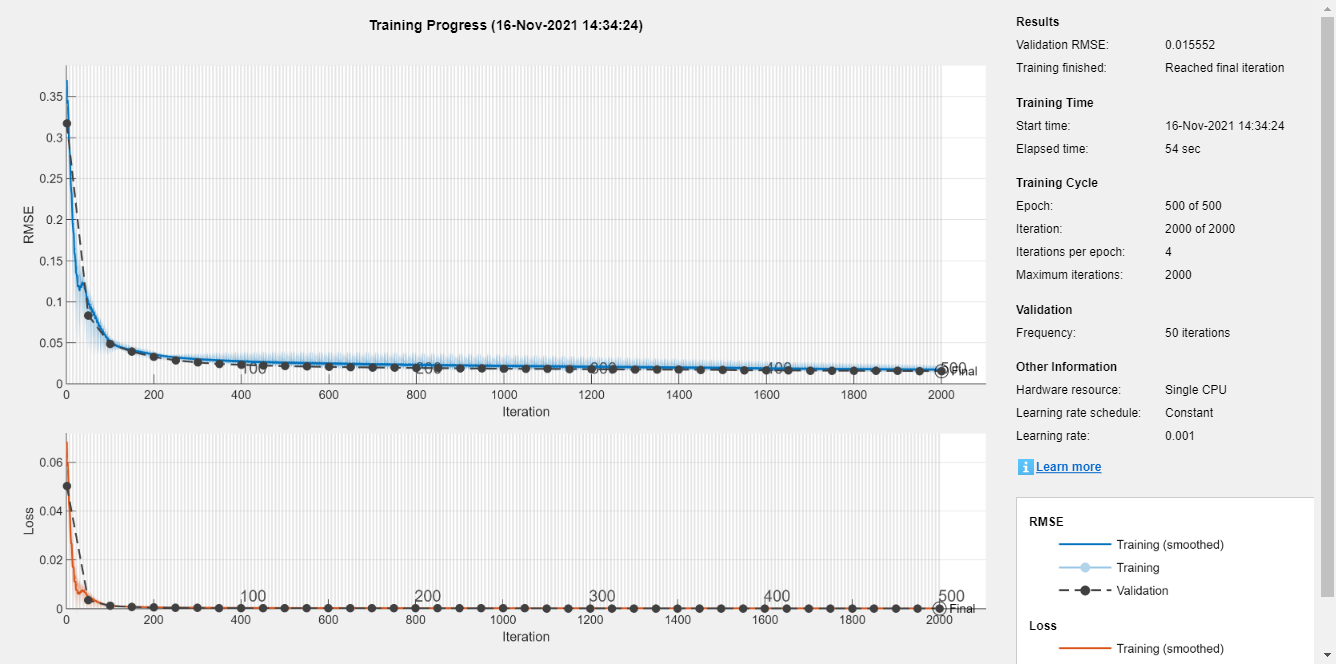

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.23 |         0.19 |       0.0271 |       0.0174 |          0.0010 |
|      13 |          50 |       00:00:06 |         0.05 |         0.03 |       0.0013 |       0.0005 |          0.0010 |
|      25 |         100 |       00:00:08 |         0.04 |         0.02 |       0.0007 |       0.0002 |          0.0010 |
|      38 |         150 |       00:00:09 |         0.03 |         0.02 |       0.0005 |   

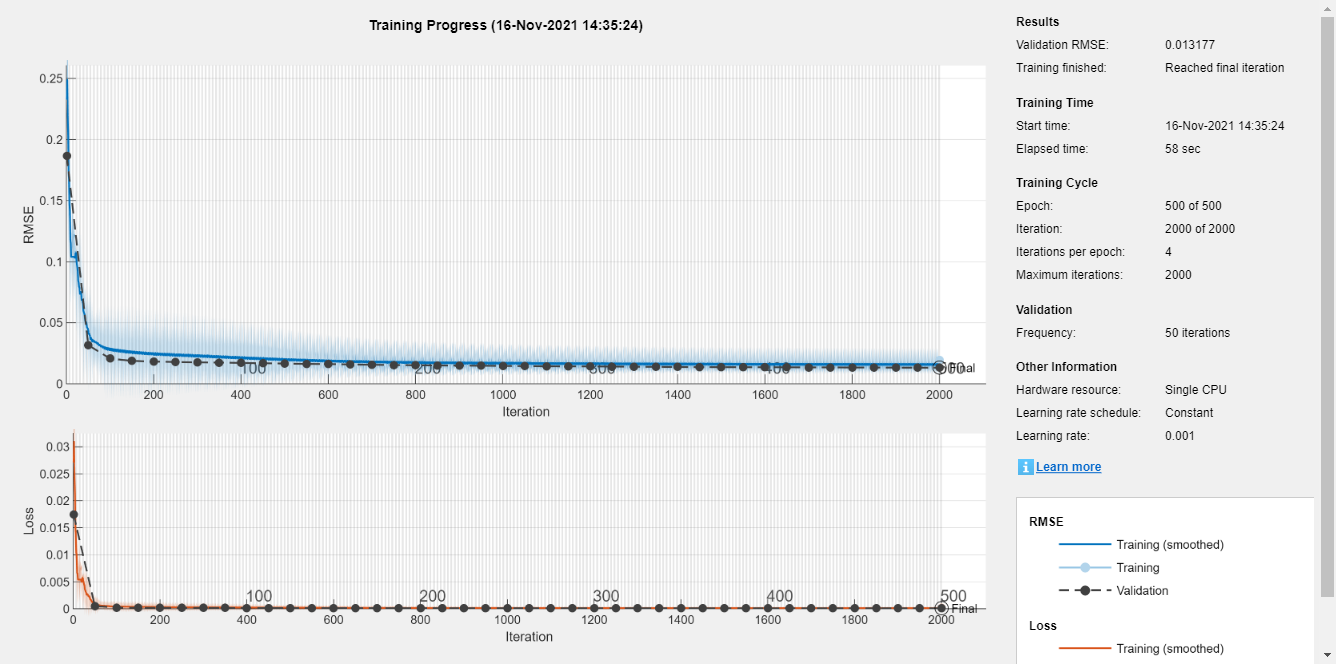

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.43 |         0.32 |       0.0930 |       0.0509 |          0.0010 |
|      13 |          50 |       00:00:06 |         0.09 |         0.08 |       0.0038 |       0.0031 |          0.0010 |
|      25 |         100 |       00:00:08 |         0.06 |         0.05 |       0.0017 |       0.0011 |          0.0010 |
|      38 |         150 |       00:00:09 |         0.04 |         0.03 |       0.0006 |       0.0005 |          0.0010 |
|      5

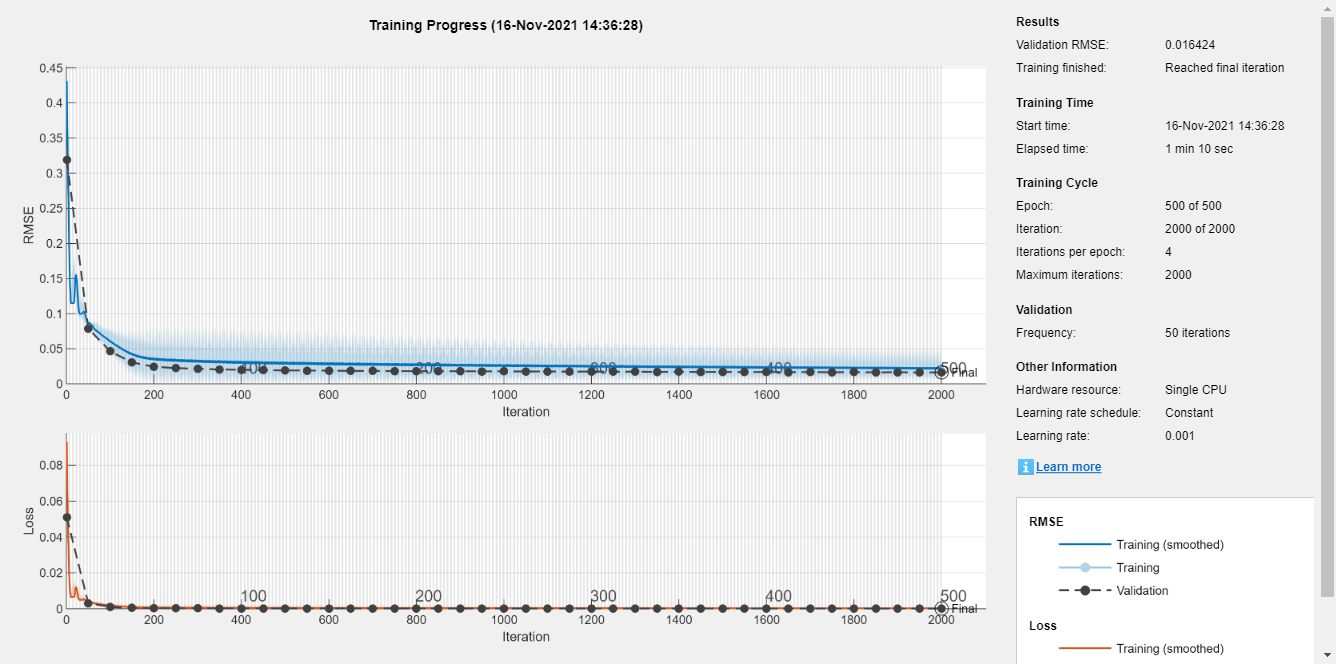

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.27 |         0.18 |       0.0364 |       0.0167 |          0.0010 |
|      13 |          50 |       00:00:10 |         0.05 |         0.04 |       0.0014 |       0.0010 |          0.0010 |
|      25 |         100 |       00:00:12 |         0.05 |         0.03 |       0.0010 |       0.0004 |          0.0010 |
|      38 |         150 |       00:00:14 |         0.03 |         0.02 |       0.0005 |       0.0002 |          0.0010 |
|      5

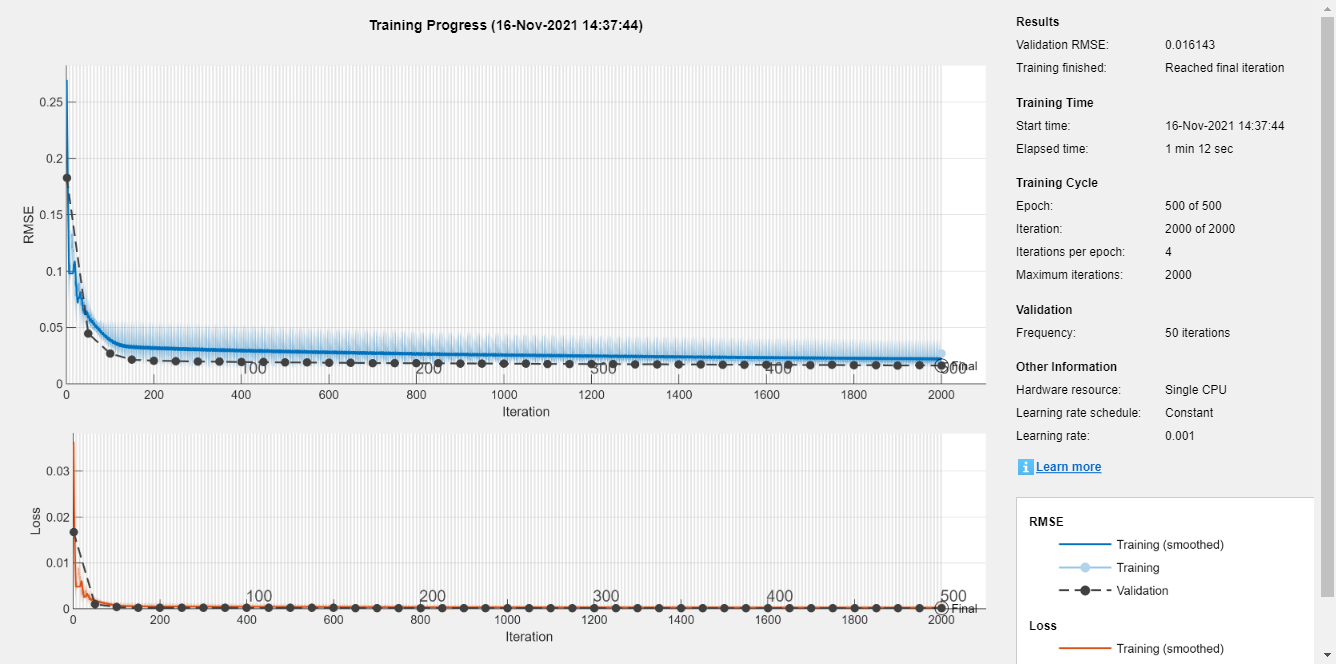

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06plus07_v2 = netFNN40;
netCNN1_05plus06plus07_v2 = netCNN1;
netCNN2_05plus06plus07_v2 = netCNN2;
netLSTM_05plus06plus07_v2 = netLSTM;
netGRU_05plus06plus07_v2 = netGRU;


# x = 05 y = cap 

BatteryNum = 5;
Train_Input = x_05;
Train_Output = yCap_05;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.25 |         0.25 |       0.0320 |       0.0301 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.05 |         0.06 |       0.0013 |       0.0018 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.02 |         0.03 |       0.0003 |       0.0005 |          0.0010 |
|     150 |         150 |       00:00:14 |         0.02 |         0.03 |       0.0001 |   

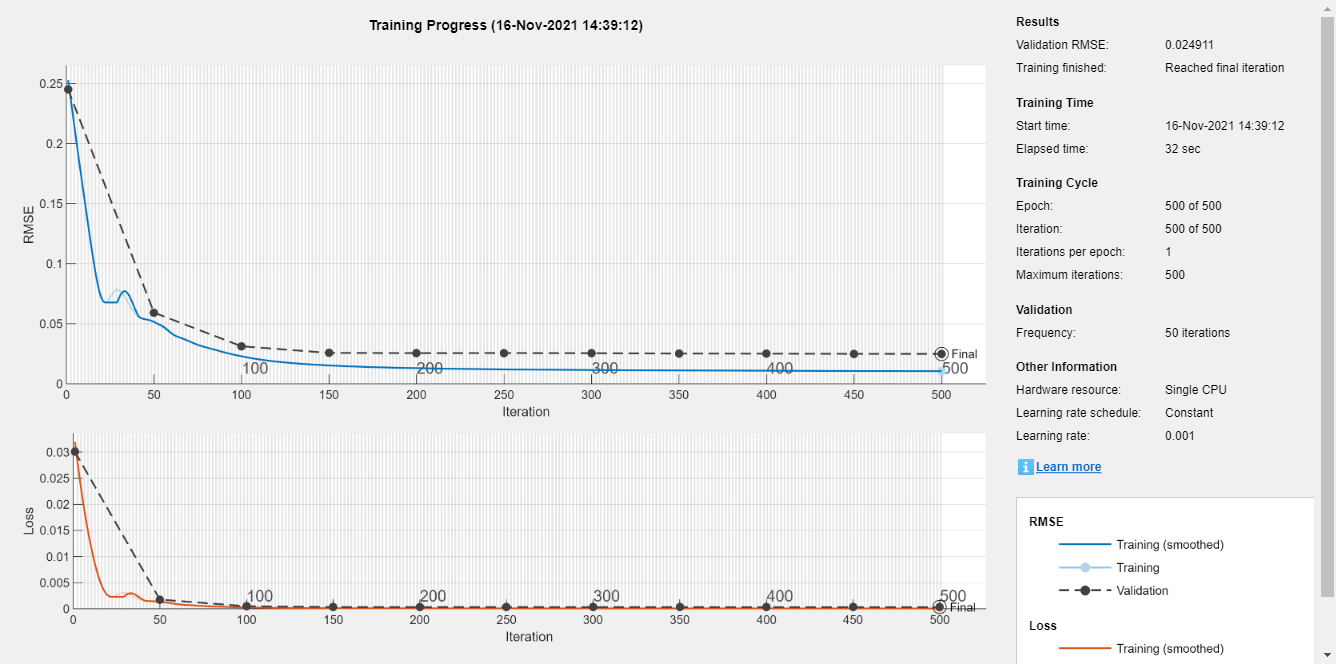

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.21 |         0.18 |       0.0229 |       0.0167 |          0.0010 |
|      50 |          50 |       00:00:12 |         0.03 |         0.04 |       0.0003 |       0.0010 |          0.0010 |
|     100 |         100 |       00:00:15 |         0.01 |         0.04 |   8.7573e-05 |       0.0007 |          0.0010 |
|     150 |         150 |       00:00:19 |         0.01 |         0.04 |   7.1175e-05 |   

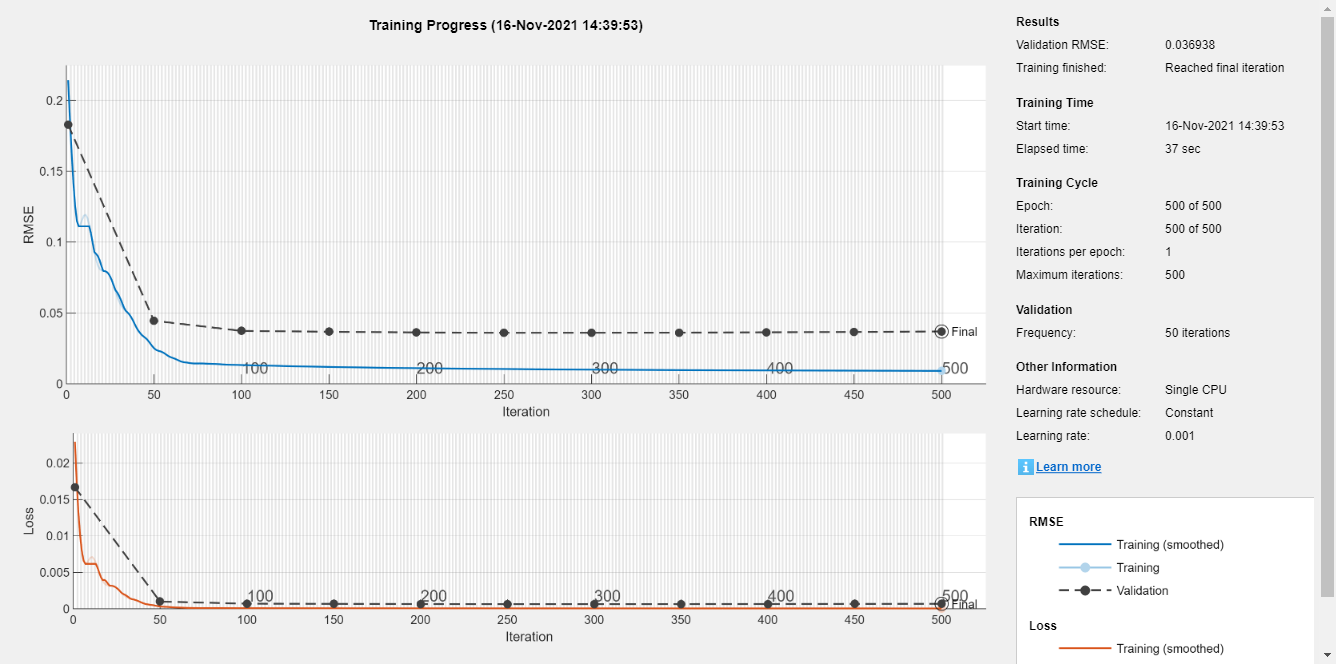

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.52 |         0.49 |       0.1376 |       0.1179 |          0.0010 |
|      50 |          50 |       00:00:16 |         0.09 |         0.10 |       0.0038 |       0.0050 |          0.0010 |
|     100 |         100 |       00:00:21 |         0.07 |         0.09 |       0.0026 |       0.0036 |          0.0010 |
|     150 |         150 |       00:00:23 |         0.06 |         0.07 |       0.0017 |       0.0026 |          0.0010 |
|     20

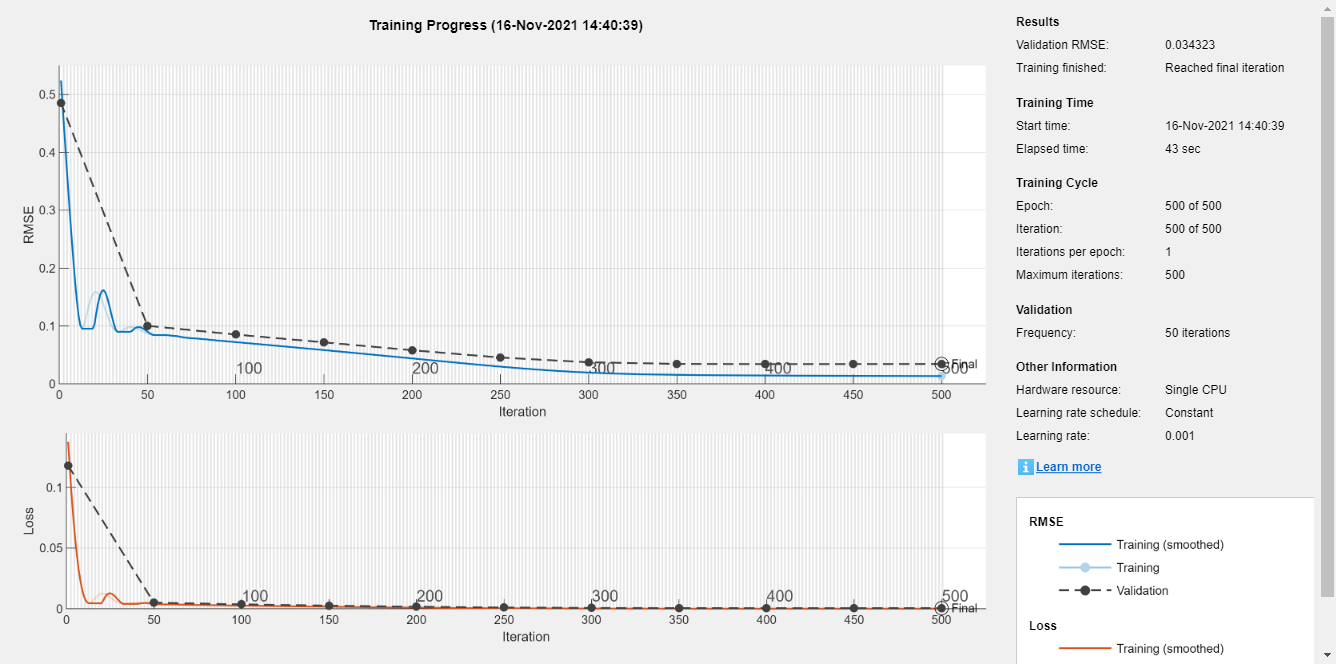

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.28 |         0.24 |       0.0384 |       0.0284 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.06 |         0.08 |       0.0020 |       0.0030 |          0.0010 |
|     100 |         100 |       00:00:17 |         0.04 |         0.05 |       0.0007 |       0.0014 |          0.0010 |
|     150 |         150 |       00:00:20 |         0.02 |         0.04 |       0.0001 |       0.0008 |          0.0010 |
|     20

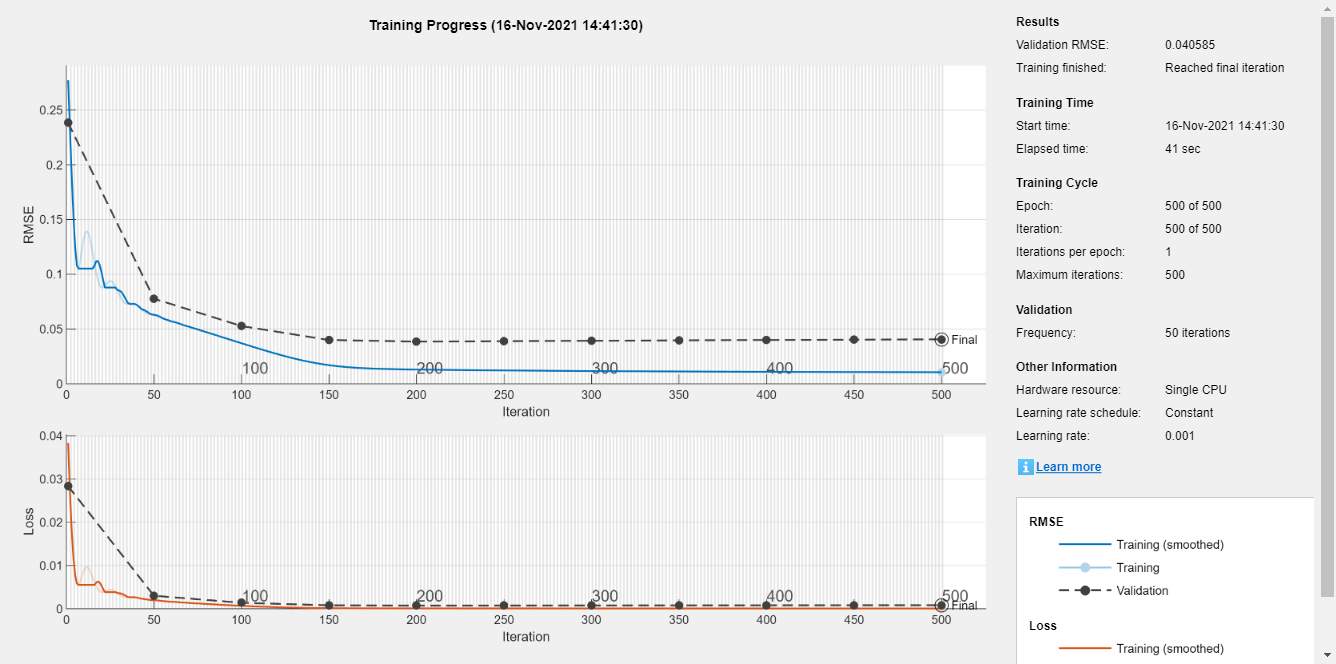

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05_v2 = netFNN40;
netCNN1_05_v2 = netCNN1;
netCNN2_05_v2 = netCNN2;
netLSTM_05_v2 = netLSTM;
netGRU_05_v2 = netGRU;


# x = 06 y = cap 

BatteryNum = 6;
Train_Input = x_06;
Train_Output = yCap_06;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |         0.35 |         0.29 |       0.0607 |       0.0419 |          0.0010 |
|      50 |          50 |       00:00:21 |         0.13 |         0.15 |       0.0087 |       0.0115 |          0.0010 |
|     100 |         100 |       00:00:23 |         0.11 |         0.11 |       0.0056 |       0.0062 |          0.0010 |
|     150 |         150 |       00:00:27 |         0.07 |         0.07 |       0.0027 |   

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

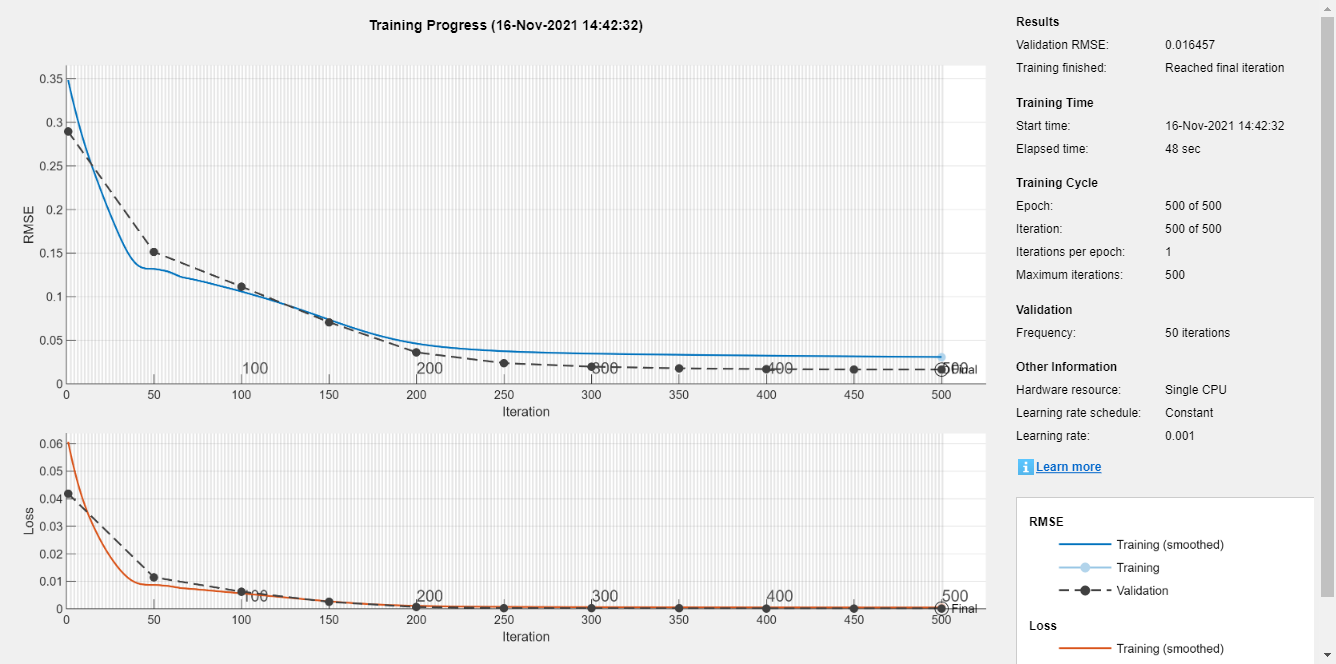

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:09 |         0.25 |         0.18 |       0.0312 |       0.0164 |          0.0010 |
|      50 |          50 |       00:00:21 |         0.05 |         0.04 |       0.0014 |       0.0008 |          0.0010 |
|     100 |         100 |       00:00:24 |         0.04 |         0.02 |       0.0006 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:26 |         0.03 |         0.02 |       0.0005 |       0.0002 |          0.0010 |
|     200 |         200 |       00:00:30 |         0.03 |         0.02 |       0.0004 |       0.0002 |          0.0010 |
|     250 |         250 |       00:00:34 |         0.03 |         0.02 |       0.0004 |       0.0001 |          0.0010 |
|     300 |         300 |       00:00:36 |         0.02 |         0.02 |       0.0003 |       0.0001 |          0.0010 |
|     350 |         350 |       00:00:42 |         0.02 |         0.02 |       0.0002 |       0.0001 |          0.0010 |
|     400 |         400 |       

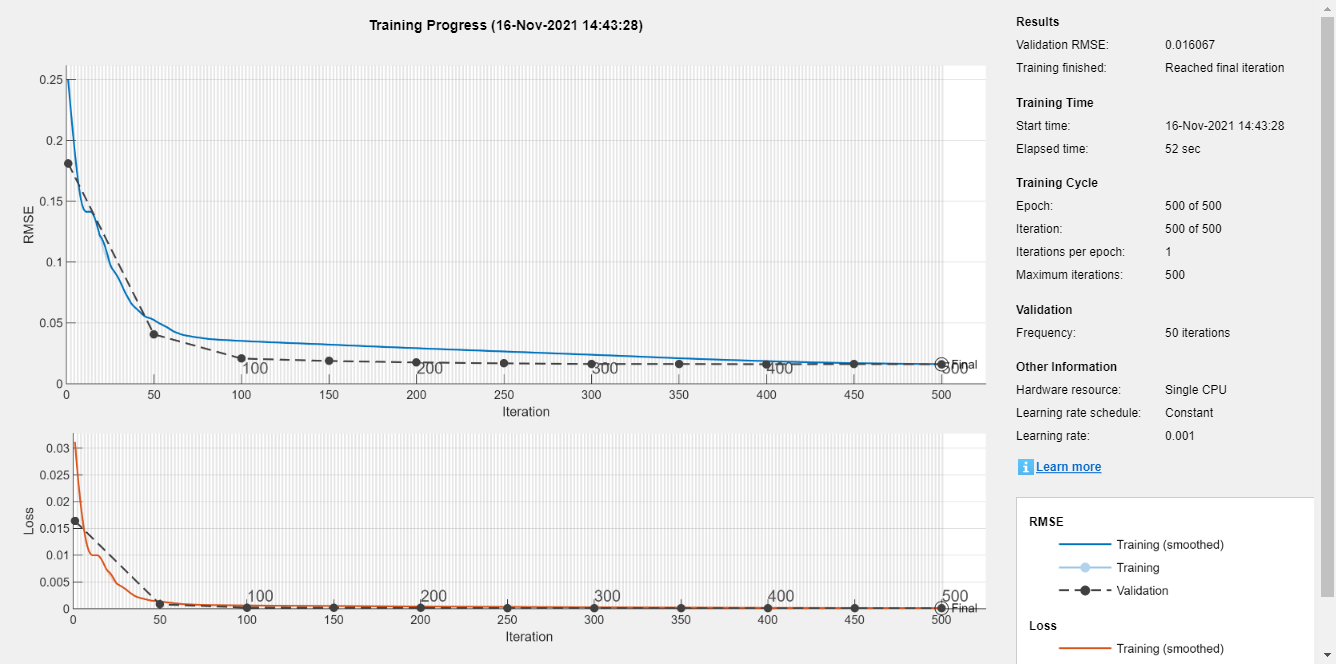

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.23 |         0.14 |       0.0259 |       0.0097 |          0.0010 |
|      50 |          50 |       00:00:15 |         0.05 |         0.05 |       0.0012 |       0.0011 |          0.0010 |
|     100 |         100 |       00:00:19 |         0.03 |         0.03 |       0.0005 |       0.0005 |          0.0010 |
|     150 |         150 |       00:00:21 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |
|     20

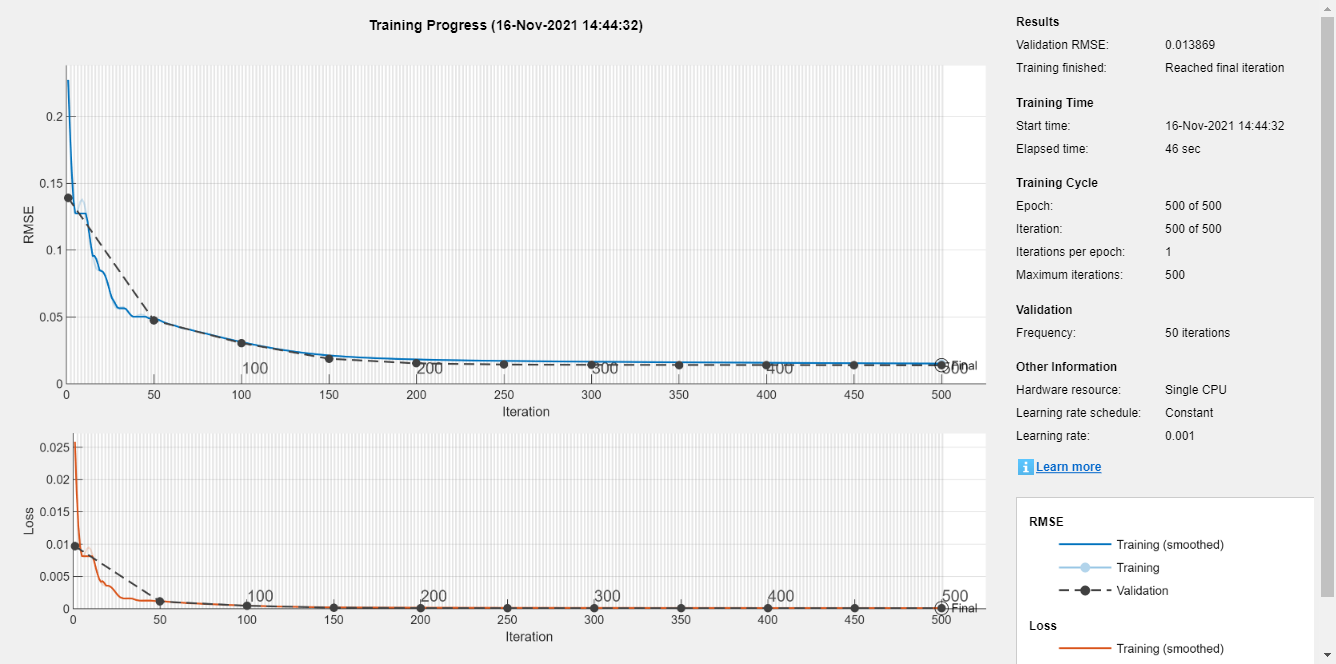

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.33 |         0.22 |       0.0533 |       0.0246 |          0.0010 |
|      50 |          50 |       00:00:15 |         0.06 |         0.07 |       0.0021 |       0.0022 |          0.0010 |
|     100 |         100 |       00:00:20 |         0.05 |         0.05 |       0.0011 |       0.0013 |          0.0010 |
|     150 |         150 |       00:00:21 |         0.03 |         0.04 |       0.0005 |       0.0007 |          0.0010 |
|     20

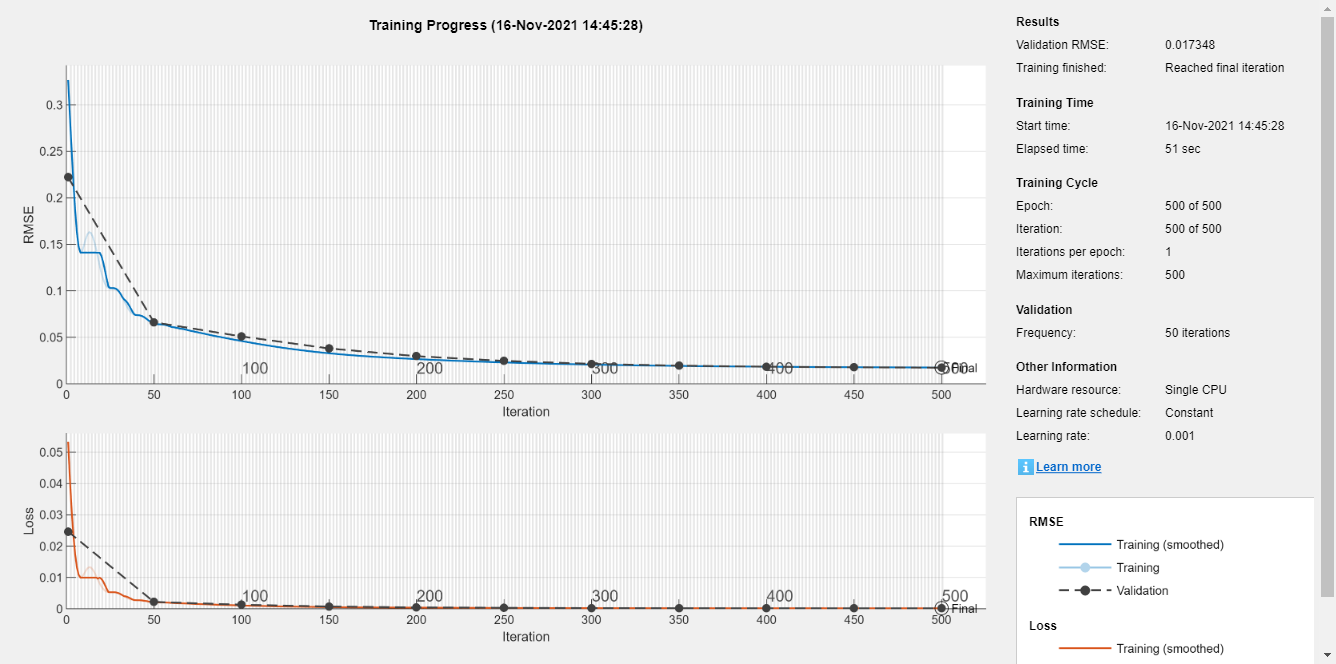

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_06_v2 = netFNN40;
netCNN1_06_v2 = netCNN1;
netCNN2_06_v2 = netCNN2;
netLSTM_06_v2 = netLSTM;
netGRU_06_v2 = netGRU;


# x = 07 y = cap 

BatteryNum = 7;
Train_Input = x_07;
Train_Output = yCap_07;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |         0.37 |         0.34 |       0.0677 |       0.0594 |          0.0010 |
|      50 |          50 |       00:00:18 |         0.10 |         0.12 |       0.0048 |       0.0072 |          0.0010 |
|     100 |         100 |       00:00:21 |         0.05 |         0.05 |       0.0014 |       0.0015 |          0.0010 |
|     150 |         150 |       00:00:24 |         0.03 |         0.02 |       0.0005 |   

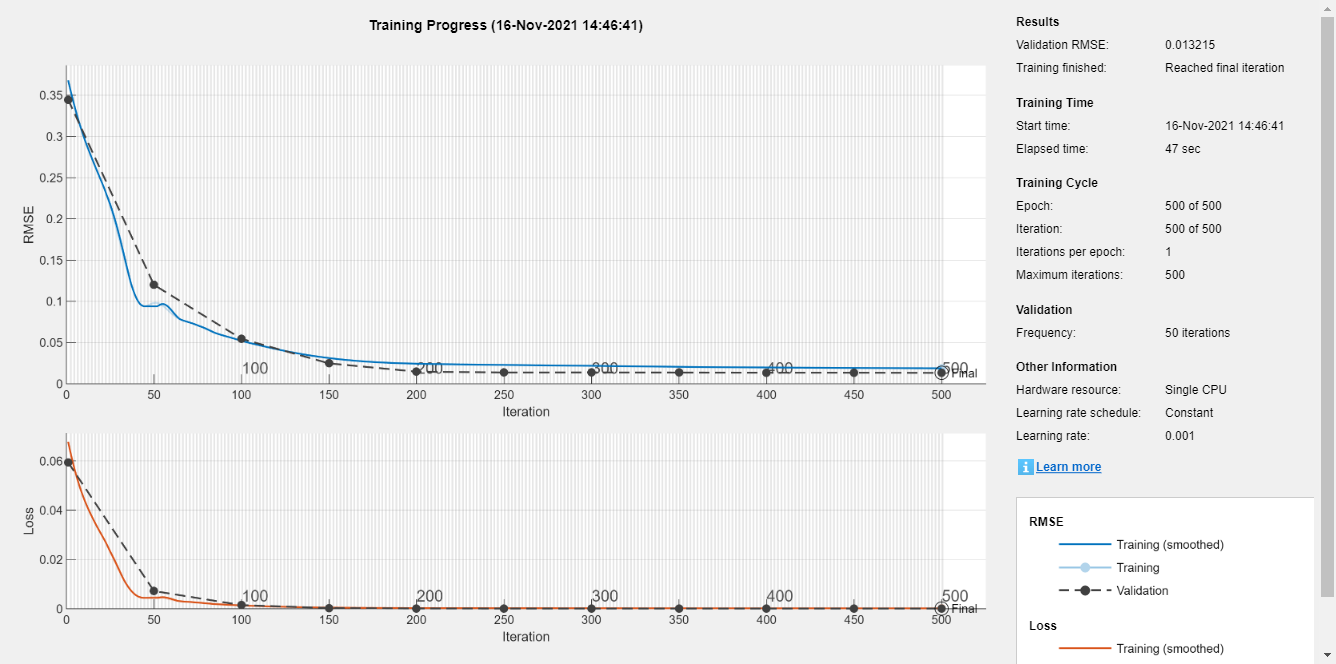

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.35 |         0.31 |       0.0625 |       0.0465 |          0.0010 |
|      50 |          50 |       00:00:10 |         0.05 |         0.05 |       0.0014 |       0.0015 |          0.0010 |
|     100 |         100 |       00:00:14 |         0.02 |         0.02 |       0.0003 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:17 |         0.02 |         0.02 |       0.0002 |   

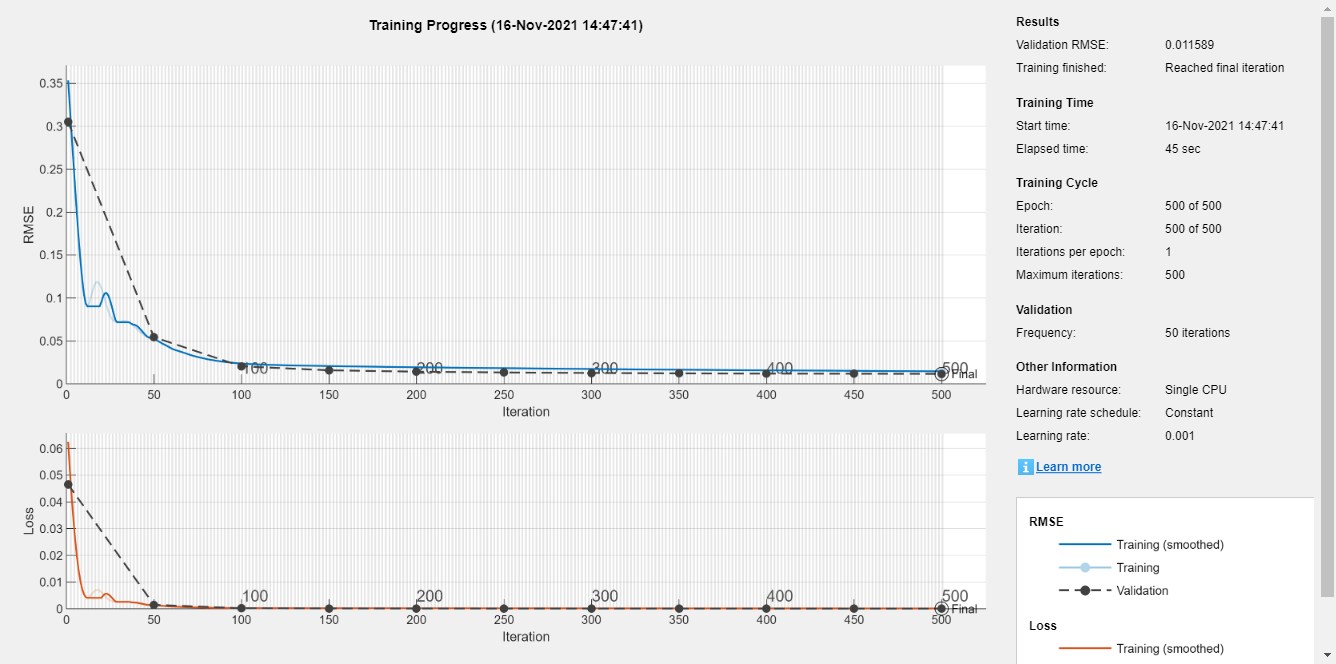

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.18 |         0.15 |       0.0159 |       0.0111 |          0.0010 |
|      50 |          50 |       00:00:13 |         0.04 |         0.04 |       0.0009 |       0.0007 |          0.0010 |
|     100 |         100 |       00:00:16 |         0.02 |         0.02 |       0.0002 |       0.0003 |          0.0010 |
|     150 |         150 |       00:00:19 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |
|     20

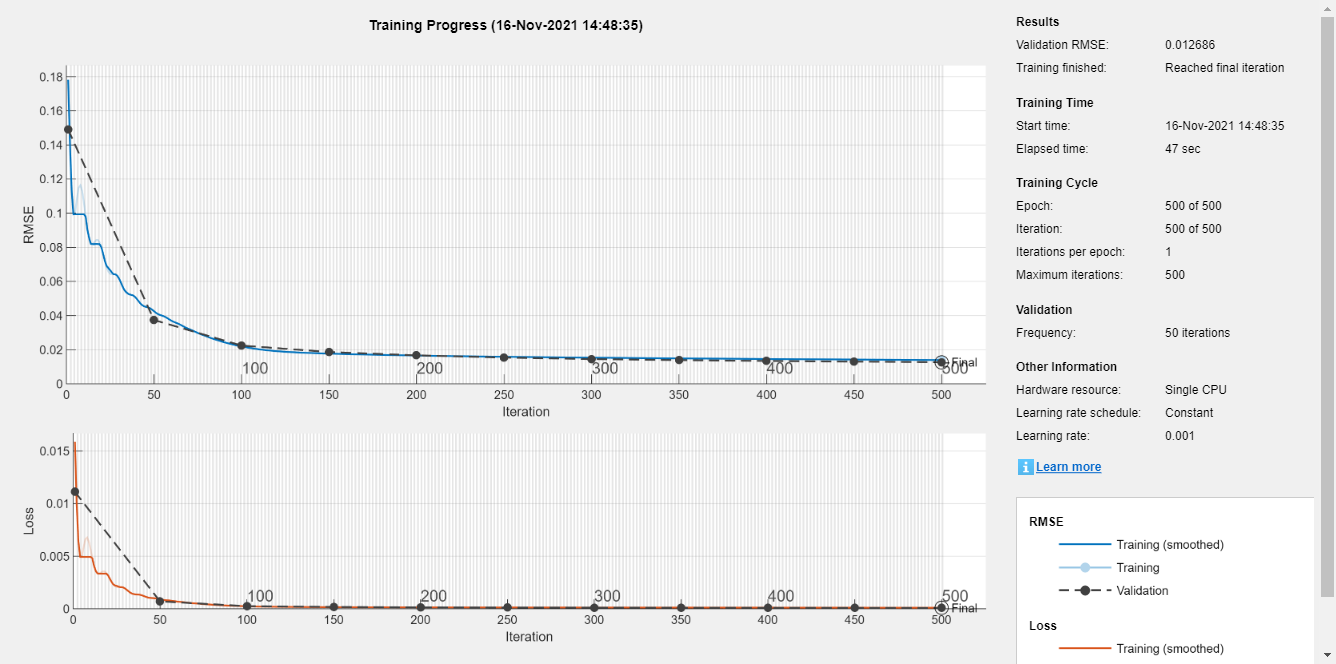

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.20 |         0.13 |       0.0210 |       0.0087 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.07 |         0.05 |       0.0021 |       0.0014 |          0.0010 |
|     100 |         100 |       00:00:18 |         0.04 |         0.04 |       0.0007 |       0.0006 |          0.0010 |
|     150 |         150 |       00:00:23 |         0.03 |         0.02 |       0.0003 |       0.0003 |          0.0010 |
|     20

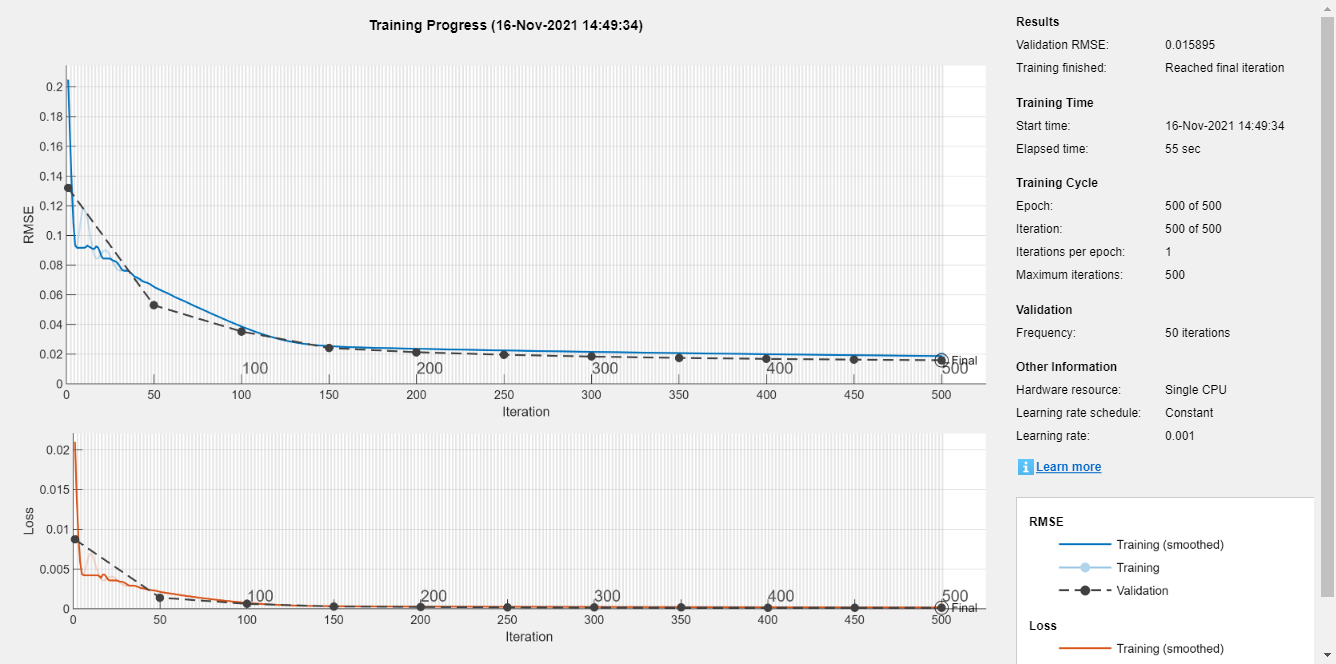

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_07_v2 = netFNN40;
netCNN1_07_v2 = netCNN1;
netCNN2_07_v2 = netCNN2;
netLSTM_07_v2 = netLSTM;
netGRU_07_v2 = netGRU;



# x = 0506 y = cap 

BatteryNum = 563;
Train_Input = x_0506;
Train_Output = yCap_0506;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:22 |         0.40 |         0.40 |       0.0816 |       0.0808 |          0.0010 |
|      50 |          50 |       00:00:33 |         0.13 |         0.15 |       0.0091 |       0.0109 |          0.0010 |
|     100 |         100 |       00:00:38 |         0.11 |         0.11 |       0.0056 |       0.0061 |          0.0010 |
|     150 |         150 |       00:00:42 |         0.07 |         0.07 |       0.0027 |   

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.24 |         0.19 |       0.0284 |       0.0186 |          0.0010 |
|      50 |          50 |       00:00:16 |         0.04 |         0.03 |       0.0007 |       0.0004 |          0.0010 |
|     100 |         100 |       00:00:32 |         0.02 |         0.02 |       0.0003 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:36 |         0.02 |         0.02 |       0.0002 |   

- LSTM : 1 lstm layer with 50 hidden units

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.19 |         0.14 |       0.0173 |       0.0098 |          0.0010 |
|      50 |          50 |       00:00:14 |         0.05 |         0.04 |       0.0011 |       0.0007 |          0.0010 |
|     100 |         100 |       00:00:17 |         0.03 |         0.03 |       0.0004 |       0.0004 |          0.0010 |
|     150 |         150 |       00:00:18 |         0.03 |         0.03 |       0.0003 |       0.0004 |          0.0010 |
|     20

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.18 |         0.14 |       0.0170 |       0.0100 |          0.0010 |
|      50 |          50 |       00:00:05 |         0.05 |         0.04 |       0.0013 |       0.0008 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.03 |         0.02 |       0.0004 |       0.0003 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.03 |         0.02 |       0.0003 |       0.0003 |          0.0010 |
|     20

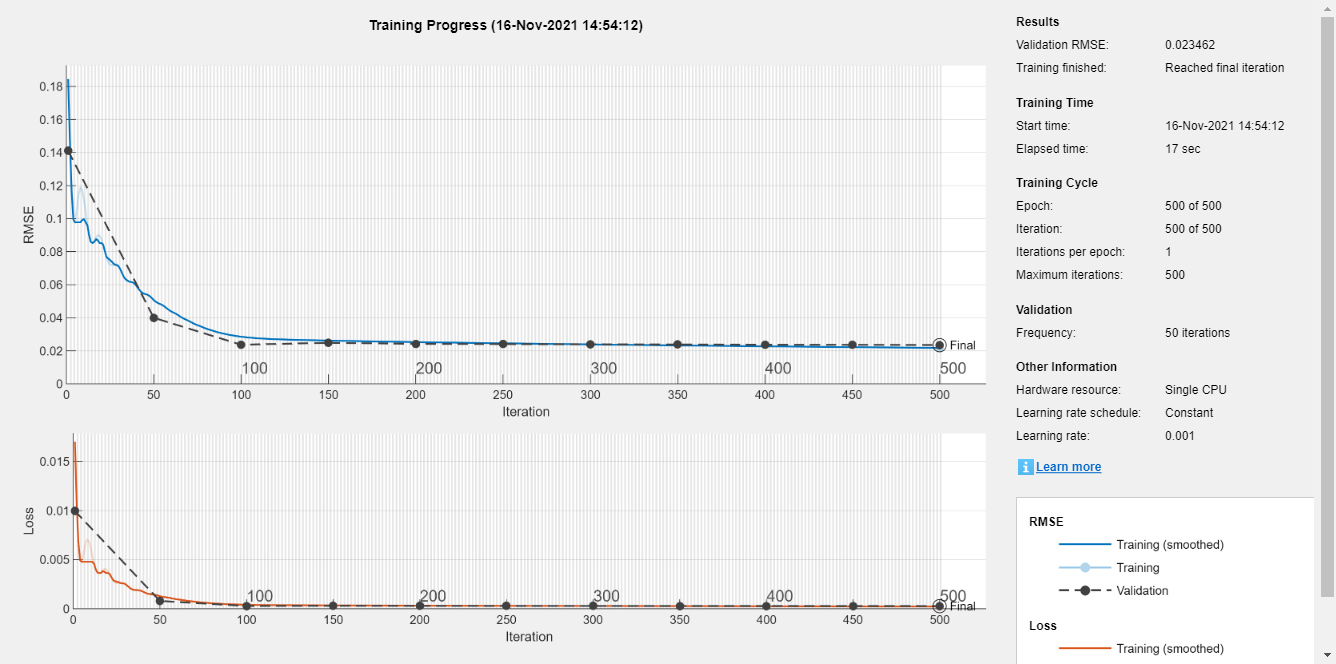

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0506_v2 = netFNN40;
netCNN1_0506_v2 = netCNN1;
netCNN2_0506_v2 = netCNN2;
netLSTM_0506_v2 = netLSTM;
netGRU_0506_v2 = netGRU;




# x = 0605 y = cap 

BatteryNum = 652;
Train_Input = x_0605;
Train_Output = yCap_0605;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.21 |         0.18 |       0.0212 |       0.0169 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.06 |         0.05 |       0.0021 |       0.0011 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.03 |         0.02 |       0.0005 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.03 |         0.02 |       0.0004 |   

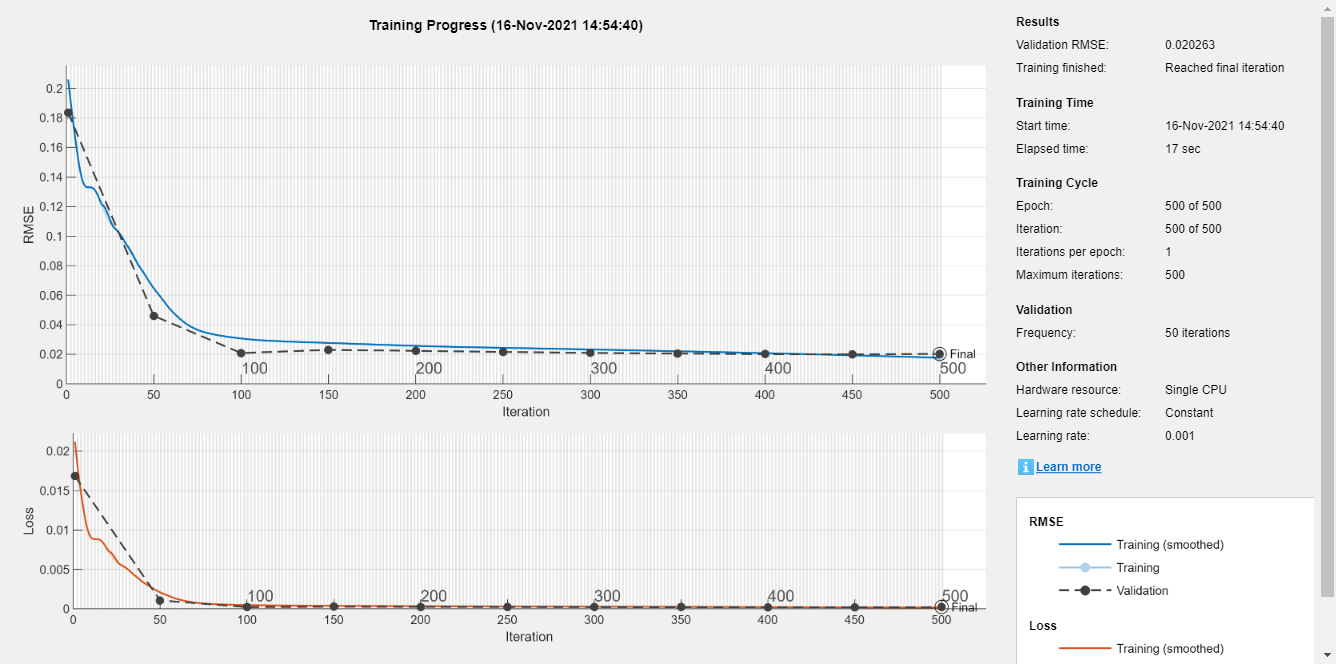

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.27 |         0.23 |       0.0359 |       0.0269 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.06 |         0.04 |       0.0017 |       0.0007 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.03 |         0.02 |       0.0005 |       0.0003 |          0.0010 |
|     150 |         150 |       00:00:08 |         0.03 |         0.03 |       0.0004 |   

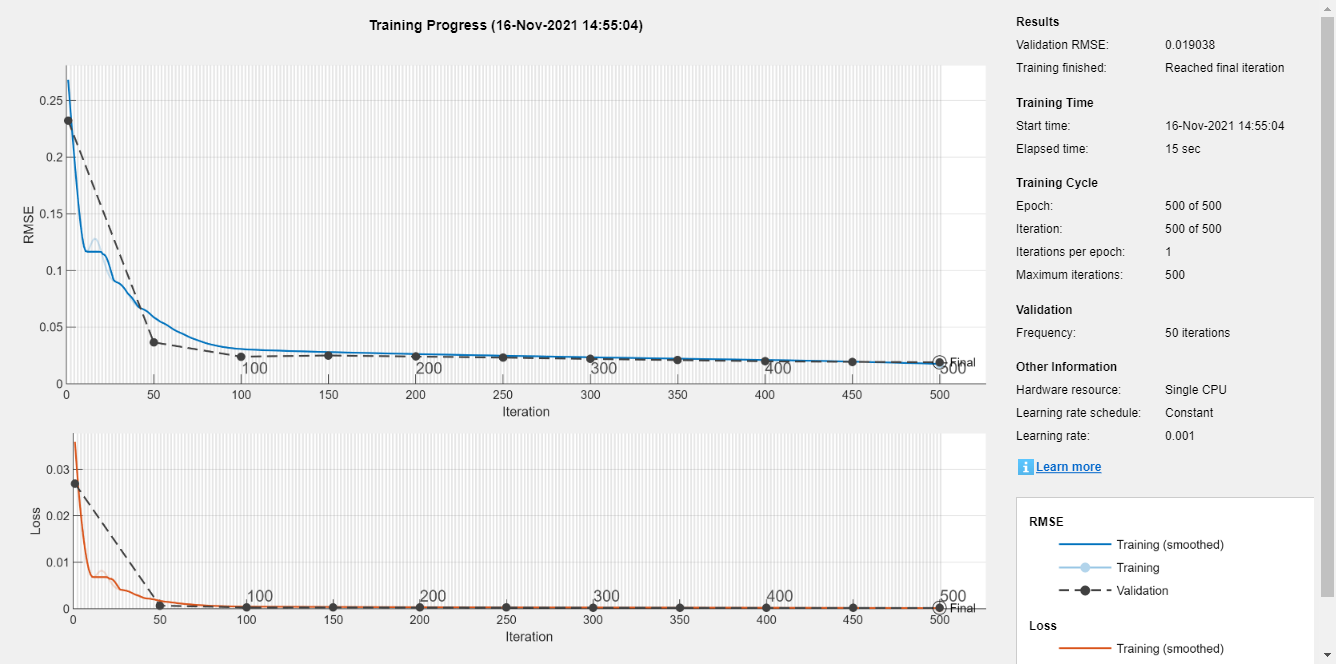

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.23 |         0.19 |       0.0257 |       0.0172 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.05 |         0.04 |       0.0012 |       0.0008 |          0.0010 |
|     100 |         100 |       00:00:09 |         0.03 |         0.02 |       0.0004 |       0.0002 |          0.0010 |
|     150 |         150 |       00:00:12 |         0.02 |         0.02 |       0.0002 |       0.0002 |          0.0010 |
|     20

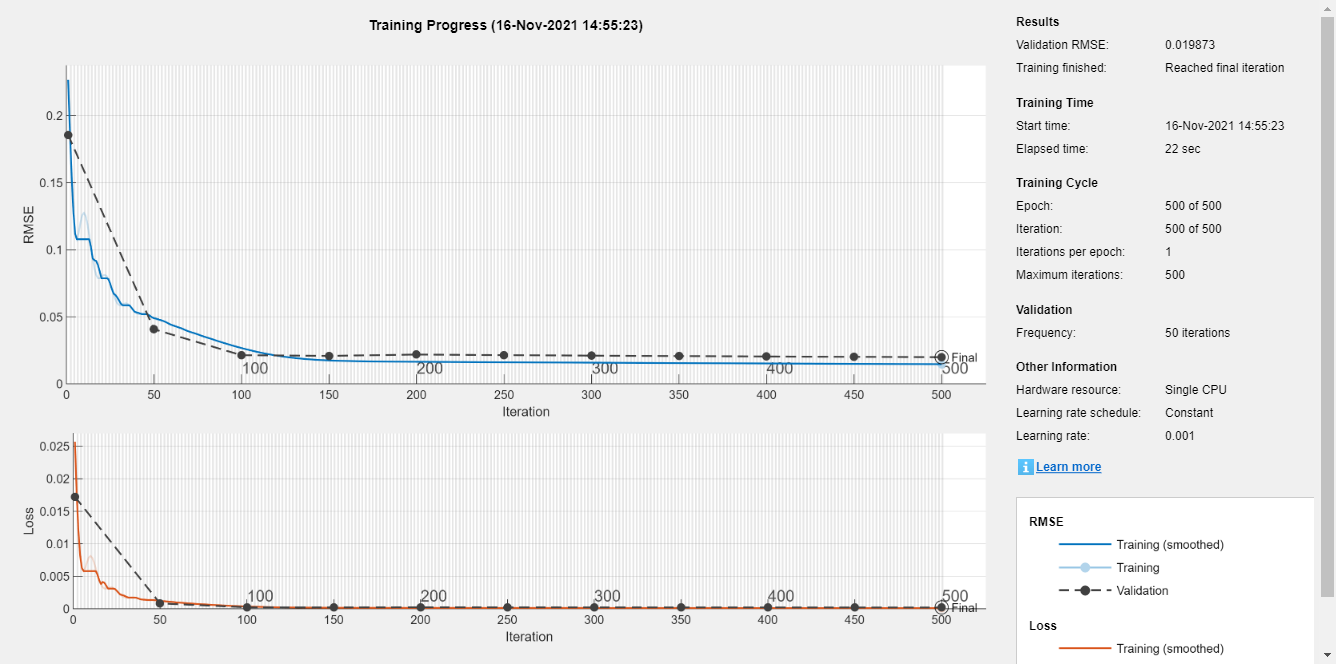

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.34 |         0.27 |       0.0584 |       0.0377 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.08 |         0.06 |       0.0031 |       0.0017 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.06 |         0.04 |       0.0019 |       0.0009 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.05 |         0.03 |       0.0012 |       0.0003 |          0.0010 |
|     20

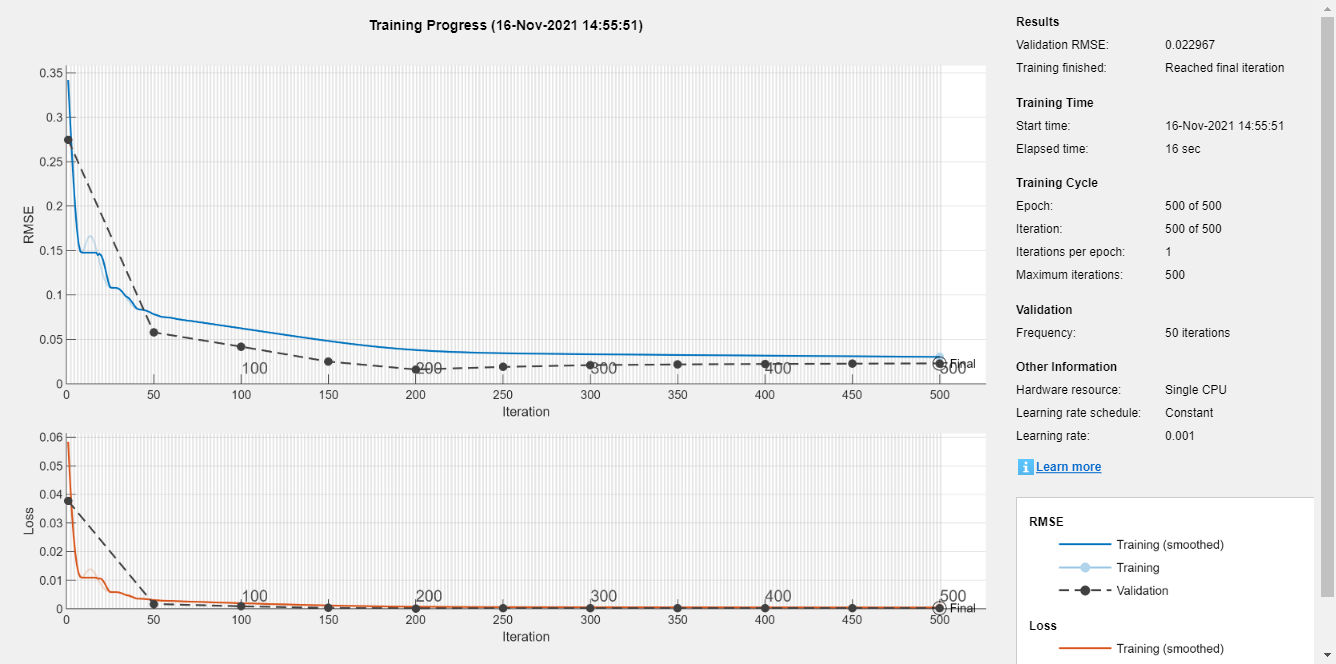

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_0605_v2 = netFNN40;
netCNN1_0605_v2 = netCNN1;
netCNN2_0605_v2 = netCNN2;
netLSTM_0605_v2 = netLSTM;
netGRU_0605_v2 = netGRU;




# x = 05plus06plus07 y = cap 

BatteryNum = 562;
Train_Input = x_05plus06;
Train_Output = yCap_05plus06;

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

layerCNN1 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.23 |         0.29 |       0.0275 |       0.0427 |          0.0010 |
|      25 |          50 |       00:00:07 |         0.06 |         0.07 |       0.0019 |       0.0025 |          0.0010 |
|      50 |         100 |       00:00:08 |         0.03 |         0.04 |       0.0004 |       0.0007 |          0.0010 |
|      75 |         150 |       00:00:09 |         0.03 |         0.04 |       0.0004 |   

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2 = [
    imageInputLayer([1, charVIT_05plus06plus07_input_size]);
    convolution2dLayer([1, 2], charVIT_05plus06plus07_input_size, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], round(charVIT_05plus06plus07_input_size / 2) , 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.20 |         0.25 |       0.0201 |       0.0305 |          0.0010 |
|      25 |          50 |       00:00:10 |         0.04 |         0.04 |       0.0008 |       0.0008 |          0.0010 |
|      50 |         100 |       00:00:12 |         0.03 |         0.03 |       0.0005 |       0.0005 |          0.0010 |
|      75 |         150 |       00:00:13 |         0.03 |         0.03 |       0.0004 |   

- LSTM : 1 lstm layer with 50 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.34 |         0.35 |       0.0594 |       0.0628 |          0.0010 |
|      25 |          50 |       00:00:07 |         0.07 |         0.07 |       0.0027 |       0.0027 |          0.0010 |
|      50 |         100 |       00:00:08 |         0.05 |         0.05 |       0.0011 |       0.0015 |          0.0010 |
|      75 |         150 |       00:00:10 |         0.04 |         0.04 |       0.0006 |       0.0009 |          0.0010 |
|     10

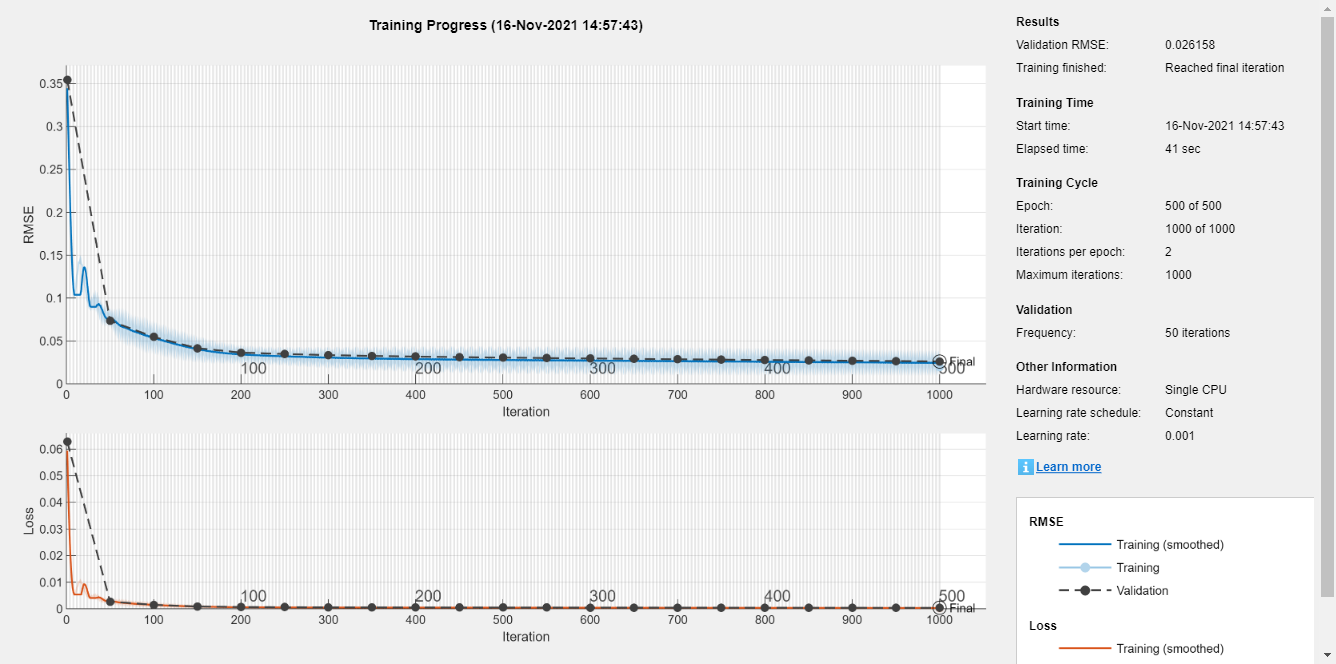

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## GRU

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.22 |         0.23 |       0.0238 |       0.0257 |          0.0010 |
|      25 |          50 |       00:00:05 |         0.06 |         0.06 |       0.0017 |       0.0017 |          0.0010 |
|      50 |         100 |       00:00:06 |         0.04 |         0.04 |       0.0006 |       0.0008 |          0.0010 |
|      75 |         150 |       00:00:06 |         0.03 |         0.04 |       0.0004 |       0.0007 |          0.0010 |
|     10

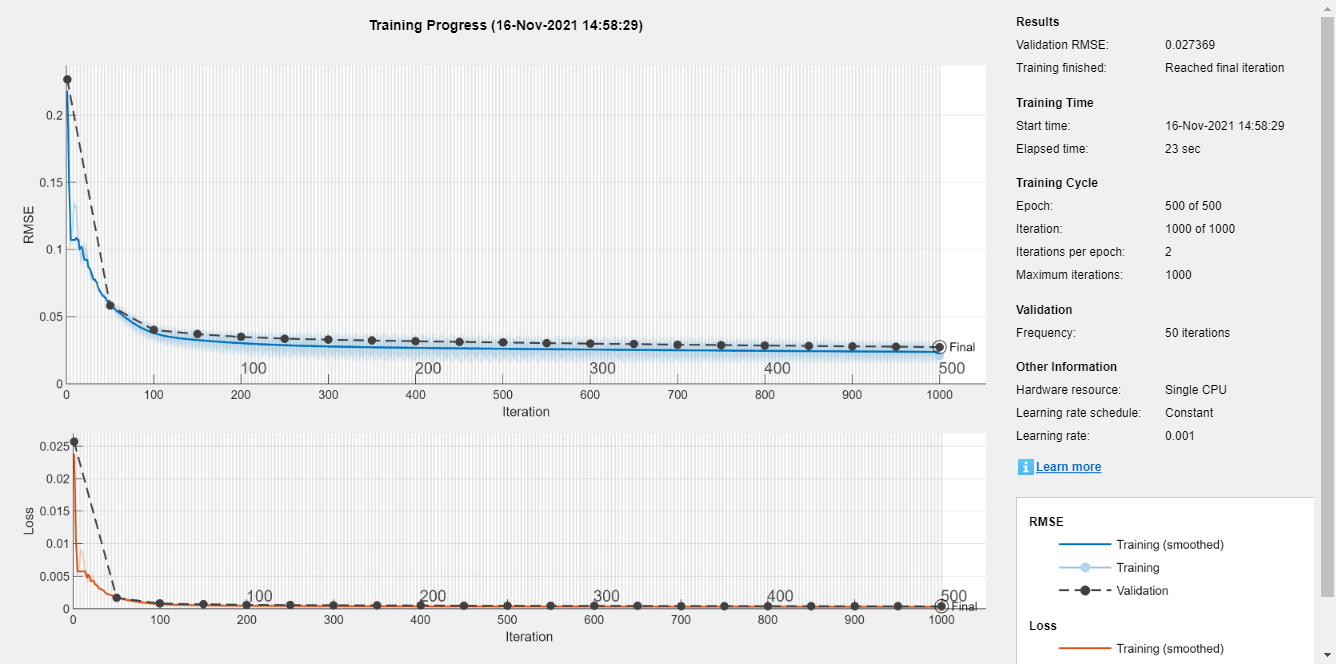

inputSize = charVIT_05plus06plus07_input_size;
numHiddenUnits = 50;

layeGRU = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

%netGRU.trainParam.showWindow=0;
netGRU = trainNetwork(traincellx, traincellyB, layersLSTM, options);

## Save model 

% https://kr.mathworks.com/matlabceloadntral/answers/264160-how-to-save-and-reuse-a-trained-neural-network

netFNN40_05plus06_v2 = netFNN40;
netCNN1_05plus06_v2 = netCNN1;
netCNN2_05plus06_v2 = netCNN2;
netLSTM_05plus06_v2 = netLSTM;
netGRU_05plus06_v2 = netGRU;



# x = ???? y = cap 

BatteryNum = 5673;
Train_Input = x_05plus06plus07;
Train_Output = yCap_05plus06plus07;

ryan_gen_data_model_desc = 'neural network model';
save('ryan_gen_data_model.mat','ryan_gen_data_model_desc');

save('ryan_gen_data_model.mat',  'netFNN40_05_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_05_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_05_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_05_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_05_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_0506_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_0506_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_0506_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_0506_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_0506_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_0605_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_0605_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_0605_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_0605_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_0605_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_05plus06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_05plus06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_05plus06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_05plus06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_05plus06_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_05plus06plus07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_05plus06plus07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_05plus06plus07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_05plus06plus07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_05plus06plus07_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netFNN40_05plus06plus07_pattern_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN1_05plus06plus07_pattern_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netCNN2_05plus06plus07_pattern_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netLSTM_05plus06plus07_pattern_v2' , '-append' )
save('ryan_gen_data_model.mat',  'netGRU_05plus06plus07_pattern_v2' , '-append' )
